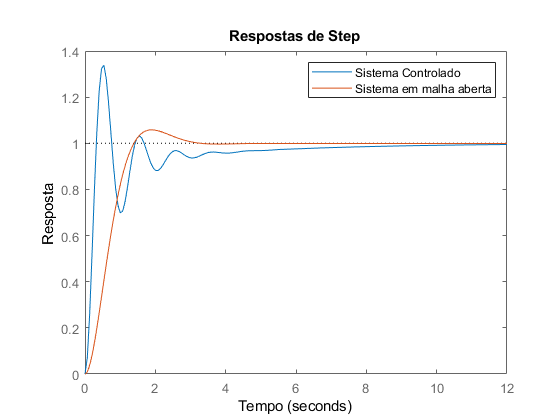

close all;
num = 5;                                    %Numerador
den = [1 3 5];                              %Denominador
sys = tf(num, den);                         %Sistema                 
L = 0.15;                                   %Atraso
K = 1;                                      %Amplitude
T = 1.32 - L;                               %Constante de tempo
%Calculo Kp, Ki, Kd da tabela para controlador P
Kp = (0.9*T)/L;
Ki = 0.3/L;
Kd = 0;
%Criando sistema de controle P
PID_controller=pid(Kp,Ki,Kd);               %Criando controlador PID
openSys = series(PID_controller,sys);       %Combinacao em serie dos sistemas
closeSys = feedback(openSys,1);             %Criando sistema em malha fechada 
%Plotando gráfico
figure;
step(closeSys);
hold on;
step(sys);
hold off; 
xlabel('Tempo');
ylabel('Resposta');
title('Respostas de Step');
legend('Sistema Controlado', 'Sistema em malha aberta');